%addpath 'iwave\development\matlab'

load_parameters

t_end = 0.01; % secs
t = 0 : t_step : t_end

t =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


reps = 1

reps = 1


Q_orig = 1e6;
Q = Q_orig / heterodyning_ratio;

band_width = f_a / Q; % or f_a_original / Q_orig

T = 20e-3;

f_axion = generate_axion_frequency_maxwellian(t, f_sampling, t_coherence, f_a, axion_linewidth);
signal = generate_axion_signal(t, f_sampling, f_axion, axion_power_over_Q * Q_orig);
noise_power = calculate_noise_power(f_sampling, T);
noise = generate_thermal_noise(t, noise_power);

tau = 0.0143e-3;

f_0s = linspace(f_a - 2*band_width, f_a + 2*band_width, 3);
L_f0s = length(f_0s);

power_dynamics = zeros(reps, L_f0s);
power_statics  = zeros(reps, L_f0s);

start_secs = 0.0015;
assert(start_secs < t(end)/3);
start = round(start_secs * f_sampling);

done = 0;
num_runs = reps * L_f0s

num_runs = 3

tic

for l = 1 : reps
    
    for i = 1 : L_f0s
        f_0 = f_0s(i);

        limiting_band = [f_0-band_width, f_0+band_width];

        [f_iwave, signal_dynamic] = do_iwave_and_resonator(t, noise, signal, f_0, band_width, f_sampling, limiting_band, tau);
        signal_static = resonator_2(noise + signal, f_0, band_width, f_sampling);

        power_dynamics(l, i) = bandpower(signal_dynamic(start:end));
        power_statics (l, i) = bandpower(signal_static (start:end));
        
    end
    done = done + L_f0s;
    frac_done = done/num_runs;
    timer_elapsed = toc;
    time_total = timer_elapsed / frac_done;
    time_remaining = time_total - timer_elapsed;
    fprintf('done %d%%, %d min gone, %d min rem\n', round(100*frac_done), round(timer_elapsed/60), round(time_remaining/60))
end

f_0 = 2.4177e+07

f_0 = 2.4178e+07

f_0 = 2.4179e+07

done 100%, 1 min gone, 0 min rem



noise_resonated = resonator_2(noise, f_0s(1), band_width, f_sampling);

power_just_noise = bandpower(noise_resonated(start:end));

snr_dynamic = mean(power_dynamics, 1) / power_just_noise - 1

snr_dynamic =    37.7365   73.3572   31.8562


snr_static  = mean(power_statics,  1) / power_just_noise - 1

snr_static =    13.9121   30.8244    7.7985


s_d_over_s_s = snr_dynamic ./ snr_static

s_d_over_s_s =     2.7125    2.3798    4.0849


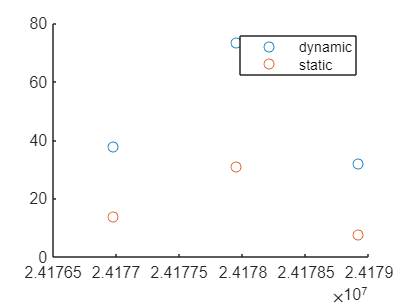

scatter(f_0s, snr_dynamic)
hold on
scatter(f_0s, snr_static)
legend('dynamic', 'static')